# **Orbital Mechanics Project: Free-Return Trajectory for Earth-Moon Mission**

Code Initiation:

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## Optimal Parking Orbit Altitude

For Hohmann Transfer between two circular orbits (from earth to parking orbit)

syms dVt dVp dVa mu ra z e
re = 6368 % km

re = 6368

ra = re + z

$$ra = z+6368$$

e = (ra - re)/(ra + re)

$$e = \frac{z}{z+12736}$$

dVp = sqrt(mu/re)*(sqrt(1 + e) - 1)

$$dVp = \left(\sqrt{\frac{z}{z+12736}+1}-1\right)\,\sqrt{\frac{\mu }{6368}}$$

dVa = sqrt(mu/ra)*(1 - sqrt(1 - e))

$$dVa = -\sqrt{\frac{\mu }{z+6368}}\,\left(\sqrt{1-\frac{z}{z+12736}}-1\right)$$

f1 = dVt == abs(dVp) + abs(dVa)

$$f1 = \mathrm{dVt}=\left|\sqrt{1-\frac{z}{z+12736}}-1\right|\,\sqrt{\frac{\left|\mu \right|}{\left|z+6368\right|}}+\left|\sqrt{\frac{z}{z+12736}+1}-1\right|\,\sqrt{\frac{\left|\mu \right|}{6368}}$$

dVt = rhs(f1)

$$dVt = \left|\sqrt{1-\frac{z}{z+12736}}-1\right|\,\sqrt{\frac{\left|\mu \right|}{\left|z+6368\right|}}+\left|\sqrt{\frac{z}{z+12736}+1}-1\right|\,\sqrt{\frac{\left|\mu \right|}{6368}}$$

derdVt = diff(dVt, z)

$$derdVt = \begin{array}{l} \frac{\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{2\,\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)\,\sqrt{\frac{\left|\mu \right|}{6368}}}{2\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{\left|\sigma_{2}-1\right|\,\left|\mu \right|\,\left(z+\bar{z}+12736\right)}{4\,{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{\left|\mu \right|}{\left|z+6368\right|}} \end{array}$$

f2 = 0 == derdVt

$$f2 = \begin{array}{l} 0=\frac{\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{2\,\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)\,\sqrt{\frac{\left|\mu \right|}{6368}}}{2\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{\left|\sigma_{2}-1\right|\,\left|\mu \right|\,\left(z+\bar{z}+12736\right)}{4\,{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{\left|\mu \right|}{\left|z+6368\right|}} \end{array}$$

x = lhs(f2)

$$x = 0$$

y = subs(rhs(f2), mu, 3.986e5)

$$y = \begin{array}{l} \frac{\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{2\,\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{\sqrt{796}\,\sqrt{49825}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)}{1592\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{99650\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12736\right)}{{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{398600}{\left|z+6368\right|}} \end{array}$$

zs = 100:50:5000

zs =          100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450        2500        2550


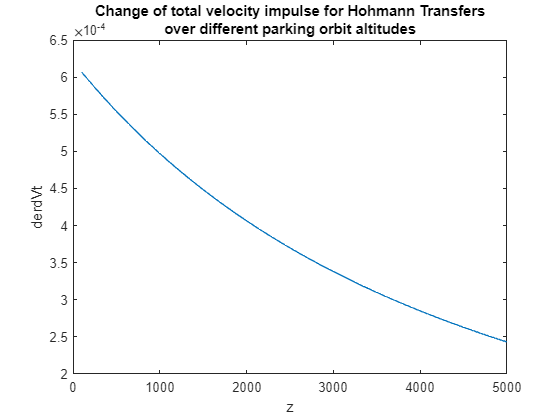

plot(zs, subs(y, z, zs))
title({'Change of total velocity impulse for Hohmann Transfers', 'over different parking orbit altitudes'})
xlabel('z')
ylabel('derdVt')

dVt = subs(dVt, mu, 3.986e5)

$$dVt = \left|\sqrt{1-\frac{z}{z+12736}}-1\right|\,\sqrt{\frac{398600}{\left|z+6368\right|}}+\frac{\sqrt{796}\,\sqrt{49825}\,\left|\sqrt{\frac{z}{z+12736}+1}-1\right|}{796}$$

plot(zs, subs(dVt, z, zs))
% title({'Total Velocity Impulse required to perform Hohmann Transfer', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('dVt')
hold on
syms dep 
dep = (mu/2)*( (1/re) - (1/ra) )

$$dep = -\frac{\mu \,\left(\frac{1}{z+6368}-\frac{1}{6368}\right)}{2}$$

dep = subs(dep, mu, 3.986e5)

$$dep = \frac{49825}{1592}-\frac{199300}{z+6368}$$

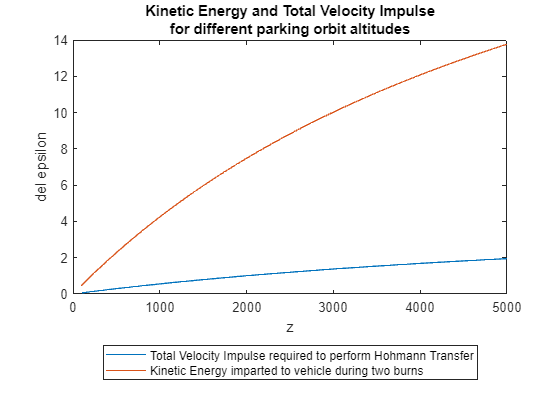

plot(zs, subs(dep, z, zs))
title({'Kinetic Energy and Total Velocity Impulse', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('del epsilon')
legend('Total Velocity Impulse required to perform Hohmann Transfer', 'Kinetic Energy imparted to vehicle during two burns', Location='southoutside')